clc
clear all
close all

# Plot M3C Variables

## Load data

Parameters

% Simulation
Tf = 0.2;
Ts = 1e-5;
Ns = round(Tf/Ts + 1);
Tsim = linspace(0, Tf, Ns);
% M3C incidence matrix
A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
% m = size(A, 2);
N = null(A, 'rational');
n = size(N, 2);

Load data

load('simulation_data.mat', 'simulation_data')

actual_run = simulation_data.run1;

% Energy
Ec = actual_run.Ec;
Ec_mean = actual_run.Ec_mean;
Ec_mean_filt = actual_run.Ec_mean_filt;

% External voltages and currents
vxy = actual_run.vxy;
von = actual_run.von;
ixy = actual_run.ixy;

% Internal voltages
vs = actual_run.vs;
vB = actual_run.vB;

% Internal currents
is = actual_run.is;
iB = actual_run.iB;
iz = actual_run.iz;
ie = actual_run.ie;

% Current references
is_ref = actual_run.is_ref;
iB_ref = actual_run.iB_ref;
iz_ref = actual_run.iz_ref;
ie_ref = actual_run.ie_ref;
ixy_ref = actual_run.ixy_ref;

## Plot variables

### Linear independent circulating currents

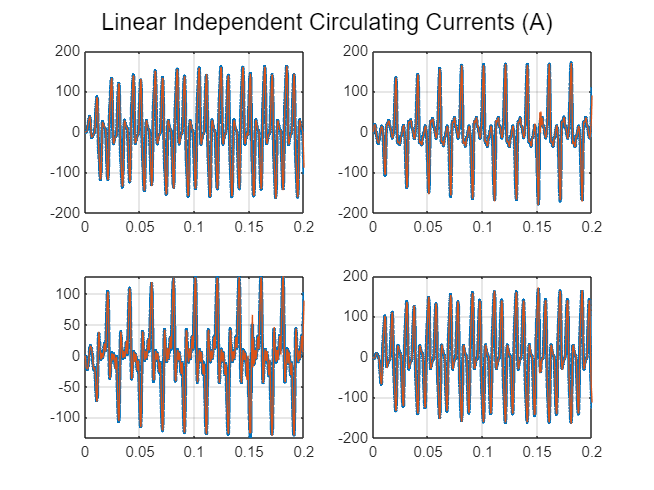

% Reference following comparation for all L.I. circulating currents
figure
subplot(ceil(n/2), 2, 1)
plot(Tsim, ie_ref(1, :), 'LineWidth', 2)
hold on
plot(Tsim, ie(1, :))
grid('on')
hold off
for idx = 2:n
    subplot(ceil(n/2), 2, idx)
    plot(Tsim, ie_ref(idx, :), 'LineWidth', 2)
    hold on
    plot(Tsim, ie(idx, :))
    grid('on')
    hold off
end
sgtitle('Linear Independent Circulating Currents (A)')

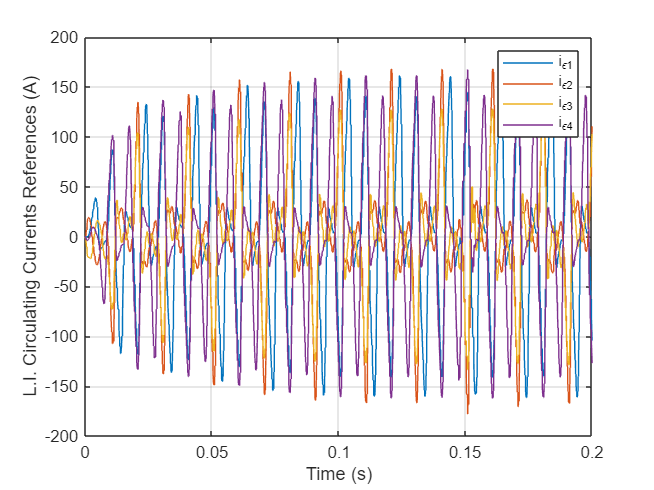


% L.I. currents references
figure
plot(Tsim, ie_ref)
ylabel('L.I. Circulating Currents References (A)')
xlabel('Time (s)')
leg = arrayfun(@(idx) ['i_{\epsilon' num2str(idx) '}'], 1:n, 'UniformOutput', false);
legend(leg)
grid on


filename = fullfile('Simulations/Figures/BCD', 'ie_ref.png');
exportgraphics(gcf, filename, 'Resolution', 300);

Error using exportgraphics
The value of 'destination' is invalid. Unable to create output file 'Simulations\Figures\BCD\ie_ref.png', No such file or directory.

### Common mode voltage

figure
plot(Tsim, von)
xlabel('Time (s)')
ylabel('Common Mode Voltage (V)')
grid on

filename = fullfile('Simulations/Figures/BCD', 'von.png');
exportgraphics(gcf, filename, 'Resolution', 300);

### Controller execution time

figure
plot(Tsim, Tex)
xlabel('Time (s)')
ylabel('CEC ET (s)')
ylim([0 0.05])

filename = fullfile('Simulations/Figures/BCD', 'Tex.png');
exportgraphics(gcf, filename, 'Resolution', 300);

External Currents

figure

subplot(2, 1, 1)
plot(Tsim, ixy_ref(1:3, :))
hold on
plot(Tsim, ixy(1:3, :), 'LineWidth', 2)
plot(Tsim, Ixd_ref)
hold off
ylabel('Input Currents (A)')
legend('i_{a}', 'i_{b}', 'i_{c}')
grid on
% xlim([3.5, 3.55])

subplot(2, 1, 2)
plot(Tsim, ixy_ref(4:6, :))
hold on
plot(Tsim, ixy(4:6, :), 'LineWidth', 2)
plot(Tsim, Iyd_ref)
hold off
ylabel('Output Currents (A)')
legend('i_{u}', 'i_{v}', 'i_{w}')
grid on
% xlim([3.5, 3.55])

xlabel('Time (s)')

filename = fullfile('Simulations/Figures/BCD', 'BCD_ixy.png');
exportgraphics(gcf, filename, 'Resolution', 300);

% filename = fullfile('Simulations/Figures/BCD', 'BCD_ixy_zoom.png');
% exportgraphics(gcf, filename, 'Resolution', 300);

Cluster Currents

figure
subplot(ceil(m/3), 3, 1)
plot(Tsim, is_ref(1, :), 'LineWidth', 2)
hold on
plot(Tsim, is(1, 1:end-1))
hold off
for idx = 2:m
    subplot(ceil(m/3), 3, idx)
    plot(Tsim, is_ref(idx, :), 'LineWidth', 2)
    hold on
    plot(Tsim, is(idx, 1:end-1))
    hold off
end
sgtitle('Cluster Currents (A)')

Circulating Currents

figure
subplot(ceil(m/3), 3, 1)
plot(Tsim, iz_ref(1, :), 'LineWidth', 2)
hold on
plot(Tsim, iz(1, :))
hold off
for idx = 2:m
    subplot(ceil(m/3), 3, idx)
    plot(Tsim, iz_ref(idx, :), 'LineWidth', 2)
    hold on
    plot(Tsim, iz(idx, :))
    hold off
end
sgtitle('Circulating Currents (A)')

figure
plot(Tsim, iz)
xlabel('Time (s)')
ylabel('Linear Independent Circulating Currents (A)')
grid on
legend('i_{z1}', 'i_{z2}', 'i_{z3}', 'i_{z4}', 'i_{z5}', 'i_{z6}', 'i_{z7}', 'i_{z8}', 'i_{z9}')

filename = fullfile('Simulations/Figures/BCD', 'BCD_iz.png');
exportgraphics(gcf, filename, 'Resolution', 300);
% 
% xlim([3.5, 3.55])
% filename = fullfile('Simulations/Figures/BCD', 'BCD_iz_zoom.png');
% exportgraphics(gcf, filename, 'Resolution', 300);

Filter Voltages

figure
vF = von+vB-vs;
% vF = is(:, 1:end-1)*R+L*diff(is, 1, 2)/Ts;
subplot(ceil(m/3), 3, 1)
plot(Tsim, vF(1, :))
for idx = 2:m
    subplot(ceil(m/3), 3, idx)
    plot(Tsim, vF(idx, :))
end
sgtitle('Filter Voltages (V)')

Cluster and Branch Voltages

figure
subplot(ceil(m/3), 3, 1)
plot(Tsim, vs(1, :), 'LineWidth', 2)
hold on
plot(Tsim, vB(1, :))
hold off
for idx = 2:m
    subplot(ceil(m/3), 3, idx)
    plot(Tsim, vs(idx, :), 'LineWidth', 2)
    hold on
    plot(Tsim, vB(idx, :))
    hold off
end
sgtitle("Cluster and Branch Voltages (V)")

Mean Capacitor Voltage

figure
plot(Tsim, vc_mean)
hold on
yline(vc_ref)
xlabel('Time (s)')
ylabel('Mean Capacitor Voltage (V)')

Capacitor Voltage Deviation, Capacitor Voltage Standard Deviation

figure
plot(Tsim, vc(:, 1:end-1))%-vc_mean)
ylabel('Capacitor Voltage (V)')% Deviation (V)')

yyaxis right
vsd = 100*std((vc(:, 1:end-1)-vc_mean)./vc_mean, 0, 1);
plot(Tsim, vsd, 'LineWidth', 2, 'Color', [0, 0, 0])
ax = gca;
ax.YColor = [0, 0, 0];
ylabel('Capacitor Voltage Standard Deviation (%)')

grid on
xlabel('Time (s)')
legend('v_{c1}', 'v_{c2}', 'v_{c3}', 'v_{c4}', 'v_{c5}', 'v_{c6}', 'v_{c7}', 'v_{c8}', 'v_{c9}', 'std')

filename = fullfile('Simulations/Figures/BCD', 'BCD_vc.png');
exportgraphics(gcf, filename, 'Resolution', 300);
% 
% xlim([3.5, 3.55])
% filename = fullfile('Simulations/Figures/BCD', 'BCD_vc_zoom.png');
% exportgraphics(gcf, filename, 'Resolution', 300);

RMS Basic Current, Circulating Current

b = 500; % Window length
izrms = mean(sqrt(movmean(iz.^2, b, 2)), 1);
iBrms = mean(sqrt(movmean(iB.^2, b, 2)), 1);

figure

plot(Tsim, iBrms, 'Color', 'b')
hold on
plot(Tsim, izrms, 'Color', 'r')
hold off
ylabel('Average RMS Current (A)')

yyaxis right
plot(Tsim, izrms./iBrms, 'LineWidth', 2, 'Color', 'm')
ax = gca;
ax.YColor = 'm';
ylabel('iz/iB RMS ratio')

grid on
xlabel('Time (s)')
legend('Basic Current', 'Circulating Current', 'Z/B ratio')

Cluster Energy

figure
plot(Tsim, Ec(:, 1:end-1))
hold on
plot(Tsim, Ec_mean, 'LineWidth', 2)
plot(Tsim, Ec_mean_filt, 'LineWidth', 2)
hold off
yline(Ec_ref, '--')
grid on
xlabel('Time (s)')
ylabel('Cluster Energy')